# Analysis Inlet CNN

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1');

Adding matlab path to: C:\Users\canca\Downloads\jorge\NN_molecular_communications\Section_IV_BioComputing\COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1


#### Parameters

%call to the parameters file
Parameters

p0=0.44146 mbar


c_Tartrazine_ini = 0.0845

c_max = 0.0845

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q_inlet_CNN=2.2 uL/min



% Load the average intensities data from the specified .mat file
dataFileName = fullfile(pwd, 'dataset', 'averageIntensities_Tx.mat');
if isfile(dataFileName)
    load(dataFileName);
else
    error('The specified file does not exist: %s', dataFileName);
end

### Experimental Work

Description: This block evaluates the experimental work from the following designs

- Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min

### Reading the Inlet CNN

% Load a video file for image processing
%Design 1_2
videoFileName_Design_1_2 = fullfile(pwd,'\experimental_work\Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Inlet_1_5_s (1).mp4');
videoObject_Design_1_2 = VideoReader(videoFileName_Design_1_2);

% Get video properties
frameRate = videoObject_Design_1_2.FrameRate

frameRate = 60

totalFrames = floor(videoObject_Design_1_2.Duration * frameRate);

fprintf('Total number of frames: %d\n', totalFrames);

Total number of frames: 813



% Define start and end time (in seconds)
startTime_Inlet_CNN = 6;  % e.g., start at 4 seconds
endTime_Inlet_CNN   = 12.5; % e.g., end at 10 seconds

% Set the video reader to the start time
videoObject_Design_1_2.CurrentTime = startTime_Inlet_CNN;


% Initialize cell array to store frames
segmentedFrames_Design_1_2 = {};

frameIdx = 1;

% Read frames between startTime and endTime
while hasFrame(videoObject_Design_1_2) && videoObject_Design_1_2.CurrentTime <= endTime_Inlet_CNN
    %Design_1_2
    frame = readFrame(videoObject_Design_1_2);
    segmentedFrames_Design_1_2{frameIdx} = frame;  %store current frame

    frameIdx = frameIdx + 1;
end

fprintf('Stored %d frames between %.2f s and %.2f s\n', numel(segmentedFrames_Design_1_2), startTime_Inlet_CNN, endTime_Inlet_CNN);

Stored 391 frames between 6.00 s and 12.50 s



% %For validation purposes
% % Create a VideoWriter object to save the processed frames
% outputVideoFileName = fullfile(pwd, ['Processed_' videoObject_Design_1_3.Name]); % Prepend "processed_" to the original video name
% outputVideo = VideoWriter(outputVideoFileName, 'MPEG-4'); % Specify the video format
% outputVideo.FrameRate = videoObject_Design_1_3.FrameRate; % Set the frame rate
% open(outputVideo); % Open the video file for writing
% 
% % Write the segmented frames to the video file
% for j = 1:length(segmentedFrames_Design_1_2)
%     writeVideo(outputVideo, uint8(segmentedFrames_Design_1_3{j})); % Convert to uint8 and write the frame
% end
% 
% close(outputVideo); % Close the video file
% fprintf('Processed video saved as: %s\n', outputVideoFileName);

### Setting coordinates at the CNN Inlet

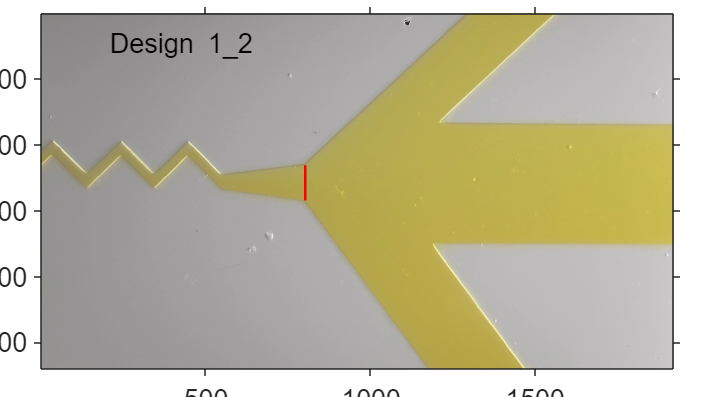

% Predefined coordinates for the line and pulse duration of 500ms
%Design 1_2
xCoords_Inlet_CNN_Design_1_2 = [802, 802]; % X coordinates
yCoords_Inlet_CNN_Design_1_2 = [569, 462]; % Y coordinates


% Plot the first frame of segmentedFrames with axes
if ~isempty(segmentedFrames_Design_1_2)
    %Design 1_2
    figure; % Create a new figure window
    imshow(segmentedFrames_Design_1_2{100}); % Display the first frame
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis
    text(200,100,"Design 1\_2",'FontSize',fontsize)
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_Inlet_CNN_Design_1_2, yCoords_Inlet_CNN_Design_1_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)
else
    warning('No frames available to display.');
end

### Intensity at Inlet CNN

% Initialize an array to store the average intensity values
averageIntensities_Inlet_CNN_Design_1_2 = zeros(1, length(segmentedFrames_Design_1_2)-1);

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames_Design_1_2)
    %Design 1_2
    frame = segmentedFrames_Design_1_2{k};    
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile = improfile(frame, xCoords_Inlet_CNN_Design_1_2, yCoords_Inlet_CNN_Design_1_2);    
    % Calculate the average intensity for the pixels along the line
    averageIntensities_Inlet_CNN_Design_1_2(k) = mean(lineProfile(:));    

end

% %Swapping the values of averageIntensities around its maximum 
% max_averageIntensities=max(averageIntensities_pipe_1);
% averageIntensities_swap_pipe_1=-(averageIntensities_pipe_1-max_averageIntensities);
% 
% max_averageIntensities=max(averageIntensities_pipe_2);
% averageIntensities_swap_pipe_2=-(averageIntensities_pipe_2-max_averageIntensities);
% 
% max_averageIntensities=max(averageIntensities_pipe_3);
% averageIntensities_swap_pipe_3=-(averageIntensities_pipe_3-max_averageIntensities);

%Concentration of Tartrazine
%Design 1_2
k=10*log10(mean(averageIntensities_Tx_Design_1_2))/c_max;%conversion rate from intensity to concentration
A_0=min(-10*log10(averageIntensities_Inlet_CNN_Design_1_2));
conc_Inlet_CNN_Exp_Design_1_2=(-10*log10(averageIntensities_Inlet_CNN_Design_1_2)-A_0)/k;


#### Evaluating the maximum of the three pipes

timeVector = linspace(startTime_Inlet_CNN, endTime_Inlet_CNN, length(conc_Inlet_CNN_Exp_Design_1_2)); % Create a time vector

%Design 1_2
[peak_Inlet_CNN_Exp_Design_1_2,idx]=max(conc_Inlet_CNN_Exp_Design_1_2);
tau_Inlet_CNN_Exp_Design_1_2=timeVector(idx);


### Plot  Experimental Concentration

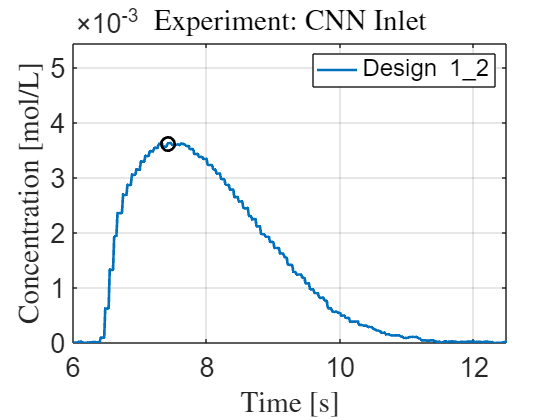


figure; % Plotting the concentration with time
plot(timeVector, conc_Inlet_CNN_Exp_Design_1_2, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers

% Plotting the maximum
plot([tau_Inlet_CNN_Exp_Design_1_2 tau_Inlet_CNN_Exp_Design_1_2],[peak_Inlet_CNN_Exp_Design_1_2 peak_Inlet_CNN_Exp_Design_1_2],'ok',LineWidth=2,MarkerSize=10)

% text(tau_Inlet_CNN_Exp_Design_1_2,1.4*peak_Inlet_CNN_Exp_Design_1_2,strcat('$\tau_\mathrm{peak}=',num2str(tau_Inlet_CNN_Exp_Design_1_2,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')
% text(tau_Inlet_CNN_Exp_Design_1_2,1.1*peak_Inlet_CNN_Exp_Design_1_2,strcat('$c_\mathrm{peak}=',num2str(peak_Inlet_CNN_Exp_Design_1_2,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')

xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Concentration [mol/L]', 'Interpreter', 'latex'); % Label for Y-axis
title('Experiment: CNN Inlet', 'Interpreter', 'latex'); % Title of the plot
axis([timeVector(1) timeVector(end) 0 1.5*peak_Inlet_CNN_Exp_Design_1_2])
grid on; % Turn on the grid
legend("Design 1\_2")
set(gca, 'FontSize', fontsize); % Set font size for axes

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  